# Digital signal processing  - Pendulum Project

**Project Group  :**

- Abed  Madi - 207670621

- Abed Deek - 318768264

- Wasem Watad - 206359424

- Mohamad Meshaal - 206365777

**Note** : all the steps will apply to all three different measurements of different threads lengths (108 [cm], 77 [cm], 40.5 [cm] )

### Importing the Acceleration data

 
clc
x_axis = (Acceleration.X)';% importing the X axis vector from Acceleration File (This applies on the other dimensions)
y_axis = (Acceleration.Y)';
z_axis = (Acceleration.Z)';

t = (Acceleration.Timestamp);% get the seconds from the timestamp table
t = time_calc(t);% build a seconds vector starting from [0 1 2 ... N] 

global thread_length % create a global variable
thread_length = len_calc(t);% calculating the length of the thread using the length of the time vector

fprintf('The length of the thread is that used is:  %.1f (cm)\n',thread_length);

The length of the thread is that used is:  40.5 (cm)


### Plotting all of the Acceleration in the three coordinates X,Y,Z 

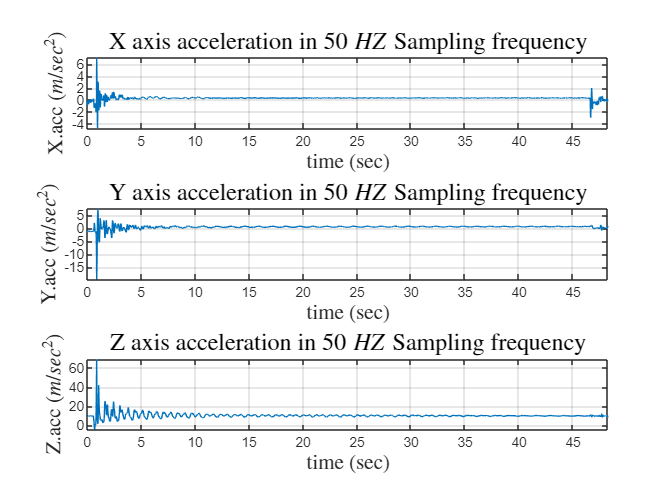

 
figure
subplot(311)
plot_func(t,x_axis,'time (sec)','X.acc ($m/sec^2$)')
title('X axis acceleration in 50 $HZ$ Sampling frequency',Interpreter='latex',FontSize=15, FontWeight= 'bold')
axis([0 t(end) min(x_axis) max(x_axis)])

subplot(312)
plot_func(t,y_axis,'time (sec)','Y.acc ($m/sec^2$)')
title('Y axis acceleration in 50 $HZ$ Sampling frequency',Interpreter='latex',FontSize=15,FontWeight= 'bold')
axis([0 t(end) min(y_axis) max(y_axis)])

subplot(313)
plot_func(t,z_axis,'time (sec)','Z.acc ($m/sec^2$)')
title('Z axis acceleration in 50 $HZ$ Sampling frequency',Interpreter='latex',FontSize=15,FontWeight= 'bold')
axis([0 t(end) min(z_axis) max(z_axis)])

**Note** : In all the measurements we took The Acceleration in Z axis (We will explain the choice in the report)

### **calculating the signal sample frequency and Changing it to 100 Hz**

 
sample_time = sample_calc(t);% calculate the Sampling time
original_sample_rate = 1/sample_time;% The Approximated sampling frequency
sample_rate = floor((1/sample_time));% sample time in seconds(the time interval between every sample)
 
n_sample_rate = 100;
m = n_sample_rate/sample_rate;
new_t = 0:sample_time/m:t(end);% create a new time vector sampled in 100HZ
interp_acc = spline(t,z_axis,new_t);% Increasing the sampling frequency to f = 100HZ of the signal and make it uniform
new_sample_rate = round(1/sample_calc(new_t));
fprintf('The original Sampling frequency : %.2f HZ\nThe New Sampling Frequency is : %d HZ\n',original_sample_rate,new_sample_rate);

The original Sampling frequency : 50.11 HZ
The New Sampling Frequency is : 100 HZ


### **The signal before and after interpolation**

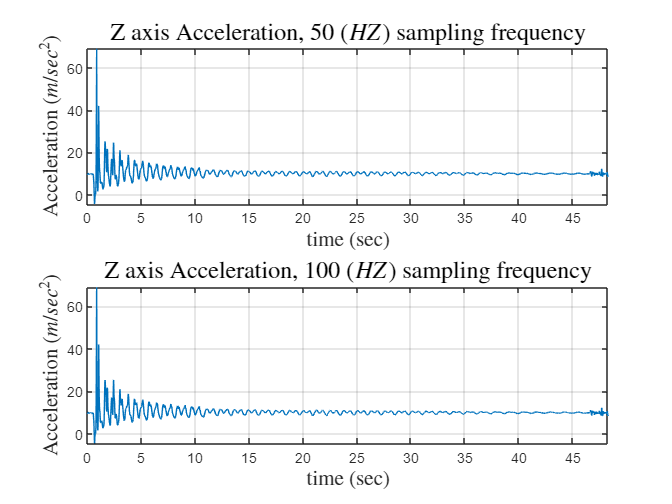

 
figure
subplot(211)
plot_func(t,z_axis,'time (sec)','Acceleration ($m/sec^2$)')
title('Z axis Acceleration, 50 ($HZ$) sampling frequency',Interpreter='latex',FontSize=15,FontWeight= 'bold')
axis([0 t(end) min(z_axis) max(z_axis)])

subplot(212)
plot_func(new_t,interp_acc,'time (sec)','Acceleration ($m/sec^2$)')
title('Z axis Acceleration, 100 ($HZ$) sampling frequency',Interpreter='latex',FontSize=15,FontWeight= 'bold')
axis([0 new_t(end) min(interp_acc) max(interp_acc)])

In this case it is not possible to see the difference between the signal in 50 Hz sample frequency and the 100 Hz 

Zoom in on a specific part of the signal to see the difference between both of difference sampling frequency

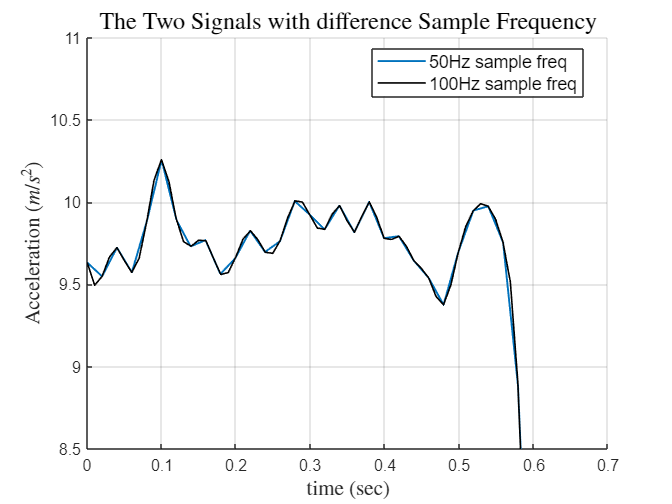

 
figure
hold on
plot(t,z_axis,LineWidth=1.2)
plot(new_t(1:length(t)), interp_acc(1:length(t)),Color =[0 0 0],LineWidth=1);grid on % to plot the two graphs...
...at the same figure we Adjust the length of the the intrpolated signal vector                                                                                     
title('The Two Signals with difference Sample Frequency',Interpreter='latex',FontSize=15,FontWeight= 'bold')
legend('50Hz sample freq','100Hz sample freq','Location','best',fontsize = 11)
xlabel('time (sec)','interpreter','latex',FontSize=13);
ylabel('Acceleration $(m/s^2)$','interpreter','latex',FontSize=13);
axis([0 0.7 8.5 11])

After we increased the sampling frequency using spline function we got a smoother signal

The z_axis vec is sampled in 50 Hz and interp_acc vec sampled in 100 Hz 

### **Calculating DFT for the z axis acceleration after changing the sample rate**

At this step and in the following Analyzes on the signal we used the iterpolated signal and with 100 HZ sampling rate and the reason is  Because with 

this signal we fixed the problem of uneven sampling time intervals

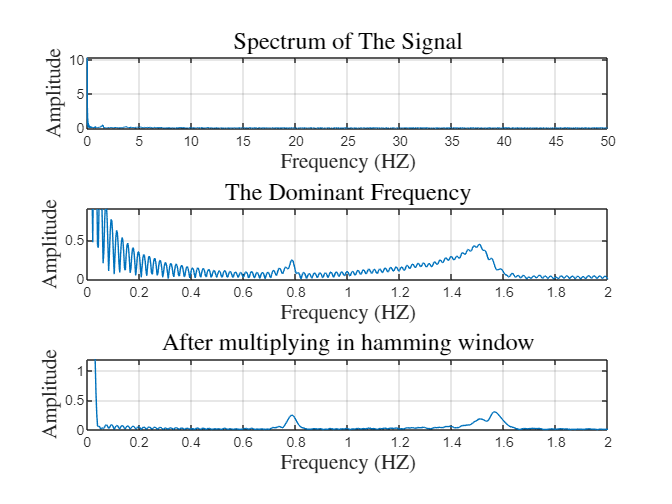

 
figure
[Z_2,Z_2_hamming ,xfft_2] = DFT(new_sample_rate, interp_acc);% calculating DFT for the z axis acceleration

figure
subplot(311)
plot_func(xfft_2, Z_2/(length(interp_acc)),'Frequency (HZ)','Amplitude')
title('Spectrum of The Signal',Interpreter='latex',FontSize=15,FontWeight= 'bold')

subplot(312)
plot_func(xfft_2, Z_2/length(interp_acc),'Frequency (HZ)','Amplitude')
title('The Dominant Frequency',Interpreter='latex',FontSize=15,FontWeight= 'bold')
axis([0 2 0 0.9])

subplot(313)
plot_func(xfft_2, Z_2_hamming,'Frequency (HZ)','Amplitude')
title('After multiplying in hamming window',Interpreter='latex',FontSize=15,FontWeight= 'bold')
axis([0 2 0 1.2])

Note : Normlized Amplitude

As we can see in The first graph the biggest peak is in the DC frequency that equal rougly to f = 0 Hz and as 

we know its not the freuency of the object

### **Filtering the signal using a Bandpass filter **

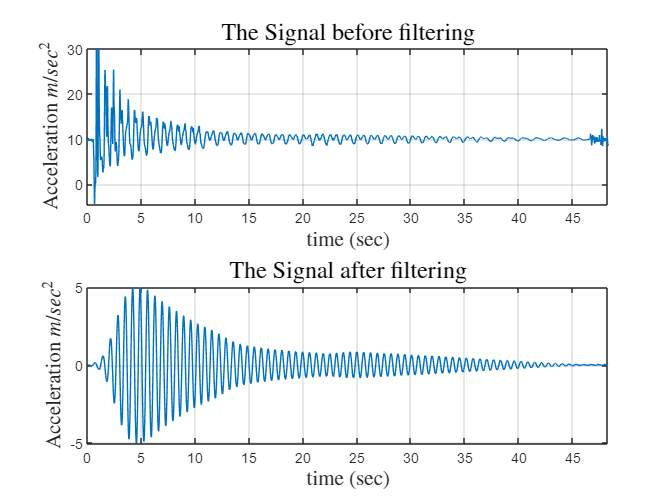

 
FilteredSignal = filt(interp_acc);% sending the signal we need to filter to the filter function

figure
subplot(211)
plot_func(new_t,interp_acc,'time (sec)','Acceleration $m/sec^2$')
title('The Signal before filtering',Interpreter='latex',FontSize=15,FontWeight= 'bold')
axis([0 new_t(end) min(interp_acc) 30])

subplot(212)
plot_func(new_t,FilteredSignal,'time (sec)','Acceleration $m/sec^2$')
title('The Signal after filtering',Interpreter='latex',FontSize=15,FontWeight= 'bold')
axis([0 new_t(end) min(FilteredSignal) max(FilteredSignal)])

**Note** :  After using a bandpass filter we actually filter the DC frequency as well, and as we can see

            the oscillations of the filtered signal is around "0" after being roughly around "9.8" 

### **The spectrum after filtering the signal .**

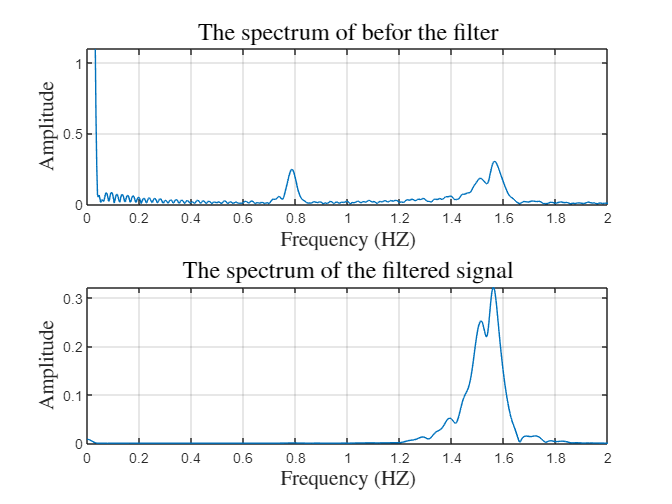

 
[~,Z_org_hamming,xfft1] = DFT(new_sample_rate, interp_acc);% the spectrum for the signal before filtring
[~,FiltSigSpectrum ,xfft2] = DFT(new_sample_rate, FilteredSignal);% the spectrum of filtered signal

figure
subplot(211)
plot_func(xfft1, Z_org_hamming,'Frequency (HZ)','Amplitude')
title('The spectrum of befor the filter',Interpreter='latex',FontSize=15,FontWeight= 'bold')
axis([0 2 0 1.1])

subplot(212)
plot_func(xfft2,FiltSigSpectrum,'Frequency (HZ)','Amplitude');grid on
title('The spectrum of the filtered signal',Interpreter='latex',FontSize=15,FontWeight= 'bold')
axis([0 2 0 max(FiltSigSpectrum)])

**Note** : Normlized Amplitude

Find the must  dominant frequency 

[maximum index1] = max(FiltSigSpectrum);
maxi1 = maximum/length(interp_acc);
oscillation_freq = xfft2(index1)/2; %The frequency value we received is 2 times larger

fprintf('The oscillation Frequency is: %.5f\n',oscillation_freq)

The oscillation Frequency is: 0.77972


The result obtained can be compared with the value obtained through the approximate formula for the oscillations frequency

$f=\frac{1}{2\Pi }\cdot \sqrt{\frac{g}{L}}$ ,      $\left\lbrack f\right\rbrack =\textrm{Hz}$


$$\begin{array}{l}
f\;\left\lbrack \textrm{Hz}\right\rbrack -\textrm{The}\;\textrm{frequency}\;\textrm{of}\;\textrm{the}\;\textrm{object}\;\textrm{oscillations}\\
g\;=\;9\ldotp 8\left\lbrack \frac{m}{s^2 }\right\rbrack -\textrm{The}\;\textrm{numerical}\;\textrm{value}\;\textrm{for}\;\textrm{the}\textrm{acceleration}\;\textrm{of}\;\textrm{gravit}\\
L\;\left\lbrack m\right\rbrack -\textrm{The}\;\textrm{length}\;\textrm{of}\;\textrm{the}\;\textrm{thread}
\end{array}$$


### **Comparing between Numerical and theoretical length of the thread using the oscillations frequency that we calculated numerically.**

**The numerical oscillations frequencies we got is :**

$F_1 =0\ldotp 77972\;\textrm{Hz}$ (40.5 cm thread length)

$F_2 =0\ldotp 54626\;\textrm{Hz}$ (77 cm thread length)

$F_3 =0\ldotp 46692\;\textrm{Hz}$ (108 cm thread length)

**calculating The length of the three threads using the numerical oscillations frequencies**


$$L_1 =\frac{g}{{\left(2\Pi f\right)}^2 }=\frac{9\ldotp 8}{{\left(2\Pi \cdot 0\ldotp 77972\right)}^2 }=\;\;0\ldotp 4083\;\left(m\right)=40\ldotp 83\;\left(\textrm{cm}\right)$$
  


$$L_2 =\frac{g}{{\left(2\Pi f\right)}^2 }=\frac{9\ldotp 8}{{\left(2\Pi \cdot 0\ldotp 54626\right)}^2 }=\;0\ldotp 83189\;\left(m\right)=83\ldotp 1893\;\left(\textrm{cm}\right)$$
 


$$L_3 =\frac{g}{{\left(2\Pi f\right)}^2 }=\frac{9\ldotp 8}{{\left(2\Pi \cdot 0\ldotp 46692\right)}^2 }=1\ldotp 13862\;\left(m\right)=113\ldotp 8626\;\left(\textrm{cm}\right)$$


**Note :** as we can see there is a deviation between the measured and calculated lengths

### **plot that contains the Numerical and Calculated frequency by the approximate formula**

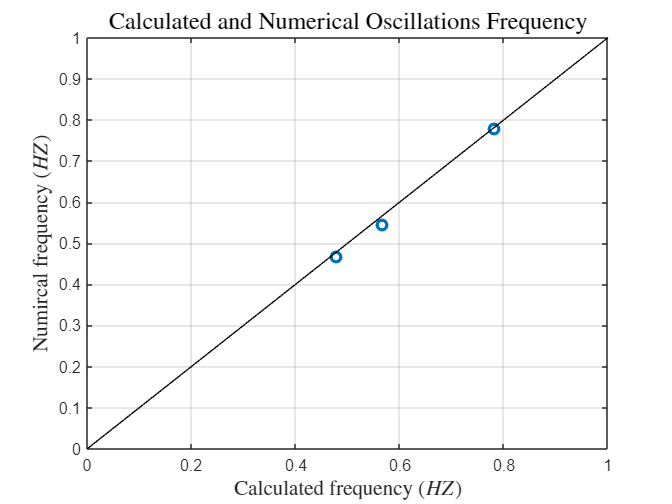

 
Calculated_frequency = [0.7828 0.56779 0.47942];
Numerical_frequency = [0.77972 0.54626 0.46692];
figure
plot(Calculated_frequency, Numerical_frequency ,'o',  LineWidth=2);grid on
title('Calculated and Numerical Oscillations Frequency',Interpreter='latex',FontSize=15,FontWeight= 'bold')
xlabel('Calculated frequency ($HZ$)',Interpreter='latex',FontSize=13,FontWeight= 'bold')
ylabel('Numircal frequency ($HZ$)',Interpreter='latex',FontSize=13,FontWeight= 'bold')
hold on
plot([0 0.5 1], [0 0.5 1], color = [0 0 0]);
axis([0 1 0 1])
hold off

### **plot that contains the lengths we measured and calculated**

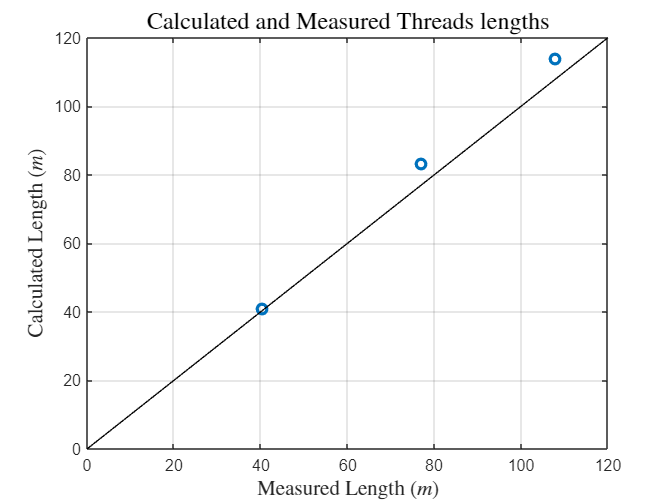

 
measured_length = [40.5 77 108];
calculated_length = [40.83 83.1893 113.8626];
figure
plot(measured_length, calculated_length ,'o',  LineWidth=2);grid on
title('Calculated and Measured Threads lengths',Interpreter='latex',FontSize=15,FontWeight= 'bold')
xlabel('Measured Length ($m$)',Interpreter='latex',FontSize=13,FontWeight= 'bold')
ylabel('Calculated Length ($m$)',Interpreter='latex',FontSize=13,FontWeight= 'bold')
hold on
plot([0 60 120], [0 60 120], color = [0 0 0]);
axis([0 120 0 120])
hold off

### **Functions section**

- time calculator function

function time = time_calc(t)

    time = zeros(1,length(t));

    for i = 1:length(time)
        time(i) =seconds(t(i) - t(1));
    end

end


- measuring the length of the thread 

 Note : Each of the sensors recordings had a different vector length

function len = len_calc(i)

    if length(i) == 2419
        len = 40.5;
    elseif length(i) == 3240
        len = 77;
    else
        len = 108;
    end
end
        

-  sample time caculator function

function sample = sample_calc(t)
    t1 = zeros(1,round((length(t))/2));
    j = 1;
    for i = 1:length(t1)
        t1(j) = t(i+1) - t(i);
        j = j+1;
    end
    sample = mean(t1);% get the mean of  the t1 vector values
    sample = sample(1);
end


- DFT calculator function

function [x ,z ,y] = DFT(Fs,func)
    
    N = length(func);
    Nfft = length(func);% detect the length of the vector
    Nfft = 2^nextpow2(Nfft*4);% zero padding
    Zz1 = fft(func,Nfft);% DFT using fft algorithim 
    Zz1 = Zz1(1:Nfft/2);% taking a one side of the DFT vector
    Zz1 = abs(Zz1);% calc the abs values of the DTF to plot the spectrum

    % in multiplying our finite time signal with a hamming window
    % help to detrmine the frequency of the frequency of oscillations 
    Zz2_hamming = fft(func.*hamming(N)',Nfft)/sum(hamming(N));% DFT using fft algorithim 
    Zz2_hamming = Zz2_hamming(1:Nfft/2);
    Zz2_hamming = abs(Zz2_hamming);% calc the abs values of the DTF to plot the spectrum
    xfft = Fs*(0:Nfft/2-1)/Nfft;% take one side of the frequency domain (The positive Frequencies)...
                                  ... and coordinate it to Hz units
        
    % return the values 
    x = Zz1;
    z = Zz2_hamming;
    y = xfft;
    
end



-  Plotting function

function plot_func(x,y,xlab,ylab)

    plot(x,y,'LineWidth',0.5);grid on
    xlabel(xlab,'interpreter','latex',FontSize=13);
    ylabel(ylab,'interpreter','latex',FontSize=13);

end



- Filter function

function FilteredSignal = filt(signal2filt)
    global thread_length
   
    % Creating a bandpass Filters using designfilt fucntion 
    % for 108 cm thread 
    hd1 = designfilt('bandpassfir','FilterOrder',500,'CutoffFrequency1',0.88,...
                    'CutoffFrequency2',0.94,'SampleRate',100,'window','hann');
    % for 77 cm thread
    hd2 = designfilt('bandpassfir','FilterOrder',500,'CutoffFrequency1',0.8,...
                      'CutoffFrequency2',1.4,'SampleRate',100,'window','hann');
    % for 40.5 cm thread
    hd3 = designfilt('bandpassfir','FilterOrder',500,'CutoffFrequency1',1.54,...
                        'CutoffFrequency2',1.58,'SampleRate',100,'window','hann');

        if thread_length == 108
            FilteredSignal =  filter(hd1, signal2filt);
        elseif thread_length == 77
            FilteredSignal = filter(hd2, signal2filt);
        else
            FilteredSignal = filter(hd3, signal2filt);
        end
end